fileNames = { % text file 읽어오기
    'XSENS\0609_LG1-000_00B4BB52.txt', 'data_FOOT', 'foot_exo_off';
    'XSENS\0609_LG1-000_00B4BAF3.txt', 'data_SHANK', 'shank_exo_off';
    'XSENS\0609_LG1-000_00B4BA83.txt', 'data_THIGH', 'thigh_exo_off';
    'XSENS\0609_LG1-000_00B4BB4F.txt', 'data_foot', 'foot_exo_on';
    'XSENS\0609_LG1-000_00B4BB4E.txt', 'data_shank', 'shank_exo_on';
    'XSENS\0609_LG1-000_00B4BB4D.txt', 'data_thigh', 'thigh_exo_on'
};

fields = {'PacketCounter', 'acc_x', 'acc_y', 'acc_z', 'gyro_x', 'gyro_Y', 'gyro_Z', 'roll', 'pitch', 'yaw'};

for i = 1:size(fileNames, 1)
    fileID = fopen(fileNames{i, 1}, 'r');
    data = textscan(fileID, '%d %f %f %f %f %f %f %f %f %f', 'HeaderLines', 5);
    fclose(fileID);
    assignin('base', fileNames{i, 2}, data);

    dataStruct = struct(); %구조체 할당
    for j = 1:length(fields) % 각 field 에 저장
        dataStruct.(fields{j}) = data{j};
    end
    assignin('base', fileNames{i, 3}, dataStruct);
end


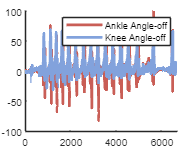

% Function to calculate pitch angle from accelerometer data
calculate_pitch = @(acc_x, acc_y, acc_z) atan2(acc_x, sqrt(acc_y.^2 + acc_z.^2)) * (180/pi);

% Calculate pitch angles for foot, shank, and thigh
theta_foot_off = calculate_pitch(foot_exo_off.acc_x, foot_exo_off.acc_y, foot_exo_off.acc_z);
theta_shank_off = calculate_pitch(shank_exo_off.acc_x, shank_exo_off.acc_y, shank_exo_off.acc_z);
theta_thigh_off = calculate_pitch(thigh_exo_off.acc_x, thigh_exo_off.acc_y, thigh_exo_off.acc_z);

% Calculate ankle and knee angles
ankle_angle_off = theta_foot_off - theta_shank_off;
knee_angle_off = theta_thigh_off - theta_shank_off;

% Calculate the mean of the first 10 values
ankle_angle_off_mean = mean(ankle_angle_off(1:10));
knee_angle_off_mean = mean(knee_angle_off(1:10));

% Subtract the mean from each angle
ankle_angle_off = ankle_angle_off - ankle_angle_off_mean;
knee_angle_off = knee_angle_off - knee_angle_off_mean;

figure; 
hold on;
plot(ankle_angle_off, 'LineStyle','-','Color',[201/255,94/255,86/255],LineWidth=2.3);
plot(knee_angle_off, 'LineStyle','-','Color',[130/255,162/255,220/255],LineWidth=2.3);
xlim([0,length(ankle_angle_off)]);
legend('Ankle Angle-off', 'Knee Angle-off');
hold off;

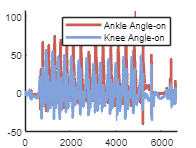

% Calculate pitch angles for foot, shank, and thigh (on)
theta_foot_on = calculate_pitch(foot_exo_on.acc_x, foot_exo_on.acc_y, foot_exo_on.acc_z);
theta_shank_on = calculate_pitch(shank_exo_on.acc_x, shank_exo_on.acc_y, shank_exo_on.acc_z);
theta_thigh_on = calculate_pitch(thigh_exo_on.acc_x, thigh_exo_on.acc_y, thigh_exo_on.acc_z);

% Calculate ankle and knee angles (on)
ankle_angle_on = theta_foot_on - theta_shank_on;
knee_angle_on = theta_thigh_on - theta_shank_on;


% Calculate the mean of the first 10 values
ankle_angle_on_mean = mean(ankle_angle_on(1:10));
knee_angle_on_mean = mean(knee_angle_on(1:10));

% Subtract the mean from each angle
ankle_angle_on = ankle_angle_on - ankle_angle_on_mean;
knee_angle_on = knee_angle_on - knee_angle_on_mean;


figure; 
hold on;
plot(ankle_angle_on, 'LineStyle','-','Color',[201/255,94/255,86/255], 'LineWidth', 2.3);
plot(knee_angle_on, 'LineStyle','-','Color',[130/255,162/255,220/255], 'LineWidth', 2.3);
xlim([0, length(ankle_angle_on)]);
legend('Ankle Angle-on', 'Knee Angle-on');
hold off;


%오일러 각도 구하기
quat1=eul2quat(deg2rad(euler_1),'XYZ');

'euler_1'은(는) 인식할 수 없는 함수 또는 변수입니다.

quat2=eul2quat(deg2rad(euler_2),'XYZ');
relativeQuat = quatmultiply(quatinv(quat1), quat2);
relativeEuler = rad2deg(quat2eul(relativeQuat, 'XYZ'));
relativeRoll=relativeEuler(:,1);
relativePitch=relativeEuler(:,2);
relativeYaw=relativeEuler(:,3);

plot(relativeRoll, 'LineStyle','-','Color',[201/255,94/255,86/255],LineWidth=2.3); 
hold on;
%plot(relativeYaw, 'LineStyle','-','Color',[130/255,162/255,220/255],LineWidth=2.3);
%plot(relativePitch, 'LineStyle','-','Color',[100/255,100/255,100/255],LineWidth=2.3);
xlim([0,num]);
ylim([-80,80])
hold off;
legend('Roll');

